## defining points

 n = 10;
 dom_size = 1;
 h= dom_size/(n-1);

## initialling the preoblem

y(1)= 0;
y(n) =1;

ynow(1)=0;
ynow(n)=1;

error=1;
error_re=1e-7;
iterations=0;

## calculation

while error > error_re
    for i=2:(n-1)
        ynow(i)=.5.*(y(i+1)+y(i-1));
        iterations= iterations+1;
    end
    % calculations of error magnitude
    error=0;
    for i=2:(n-1)
        error=error+ abs(y(i)-ynow(i));
    end
    y=ynow;
end

## plotting

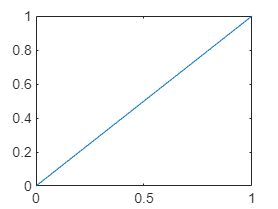

x=((1:n)-1).*h;
figure; plot(x,y)